#  ENME462 Studio 10 Root Locus Compensator Design

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

## Response:

***1) Transient response (unity step input)***

First order system $T(s)=\frac{a}{s+a}=\frac{1}{\tau s+1}$

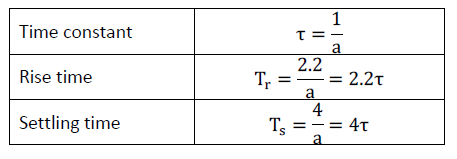

Second order system $T(s)=\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}$

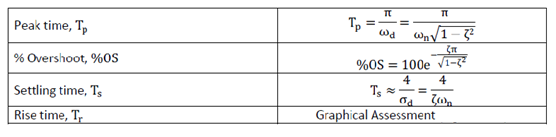

## Compensators: 

**1) Transient Response Compensators**

*i) ****PD**** compensators: *


$$G_c(s)=K_P+K_Ds=K_D(s+K_P/K_D)$$


PD compensator improves the ransient response via *re-shaping* the original system's root locus. An additional zero provides 1 DoF to adjust the root locus angle condtion.

*ii) ****Lead**** compensators*


$$G_c(s)=K\frac{s+z_c}{s+p_c}, \qquad |p_c| <|z_c|$$


Lead compensator improves the transient response via *re-shaping* the original system's root locus. An additional zero/pole pair is placed at a location so that the root locus angle condition can be satisfied at the target closed-loop poles.

**2) Steady-state error Compensators **

*i) ****PI**** compensators*


$$G_c(s)=K_P+\frac{K_I}{s}=\frac{K_P(s+K_i/K_P)}{s}$$


PI compensator adds a pole at he origin and a zero close to the origin to prevent the additional pole from significantly distorting the shape of the original system's root locus. 

ii) **Lag** compensators

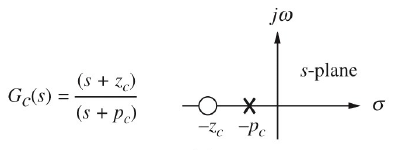

Lag compensator increase the statc error constants, without distorting the shape of the original systems' root locus.

## Exercise 

Consider the unity feedback system with 


$$G(s)=\frac{K}{(s+4)(s+6)(s+10)}$$


i) Use MATLAB along with hand calculations to design a PID compensator so that the closed-loop system will have % OS <25% and Ts < 2 sec for a step input and zero steady-state error for step and ramp inouts.

ii) Plot the root locus of the compensated system in i) and the step response and show that the specifications are met.